# **Fourier Transforms**

The Fourier transform is a mathematical formula that relates a signal sampled in time or space to the same signal sampled in frequency. In signal processing, the Fourier transform can reveal important characteristics of a signal, namely, its frequency components.

The Fourier transform is defined for a vector $x$ with $n$ uniformly sampled points by


$$y_{k+1} = \sum_{j=0}^{n-1}\omega^{jk}x_{j+1}$$


$\omega = e^{-2\pi i/n}$ is one of $n$ complex roots of unity where $i$ is the imaginary unit. For $x$ and $y$, the indices $j$ and $k$ range from $0$ to $n-1$.

The `fft` function in MATLAB® uses a fast Fourier transform algorithm to compute the Fourier transform of data. Consider a sinusoidal signal `x` that is a function of time `t` with frequency components of 15 Hz and 20 Hz. Use a time vector sampled in increments of $\frac{1}{50}$ of a second over a period of 10 seconds.

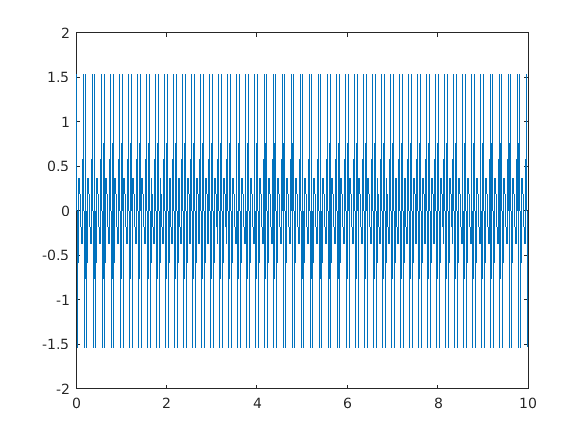

t = 0:1/50:10-1/50;                     
x = sin(2*pi*15*t) + sin(2*pi*20*t);
plot(t,x)

Compute the Fourier transform of the signal, and create the vector `f` that corresponds to the signal's sampling in frequency space. 

y = fft(x);     
f = (0:length(y)-1)*50/length(y);

When you plot the magnitude of the signal as a function of frequency, the spikes in magnitude correspond to the signal's frequency components of 15 Hz and 20 Hz.  

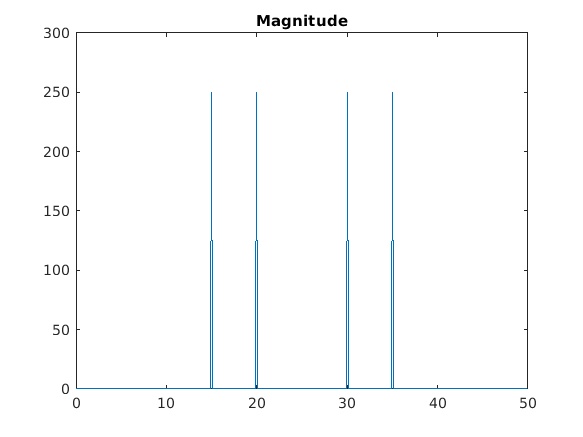

plot(f,abs(y))
title('Magnitude')

The transform also produces a mirror copy of the spikes, which correspond to the signal's negative frequencies. To better visualize this periodicity, you can use the `fftshift` function, which performs a zero-centered, circular shift on the transform.

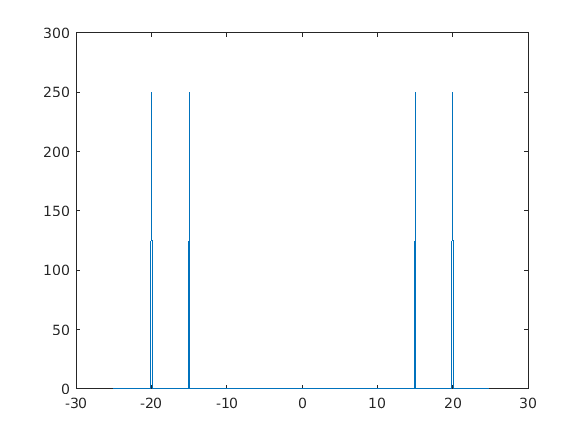

n = length(x);                         
fshift = (-n/2:n/2-1)*(50/n);
yshift = fftshift(y);
plot(fshift,abs(yshift))

## Noisy Signals

In scientific applications, signals are often corrupted with random noise, disguising their frequency components. The Fourier transform can process out random noise and reveal the frequencies. For example, create a new signal, `xnoise`, by injecting Gaussian noise into the original signal, `x`.

snrdb = -2;                % SNR in dB
snr = db2pow(snrdb);      % SNR in linear scale
spower = 1;               % signal power is 1 (sum of two sine waves with unit amplitudes - 1/2 is the power of each signal)
npower = spower/snr;           % noise power
namp = sqrt(npower/2);    % noise amplitude in each channel
xnoise = x + namp*randn(size(t));

Signal power as a function of frequency is a common metric used in signal processing. Power is the squared magnitude of a signal's Fourier transform, normalized by the number of frequency samples. Compute and plot the power spectrum of the noisy signal centered at the zero frequency.  Despite noise, you can still make out the signal's frequencies due to the spikes in power. 

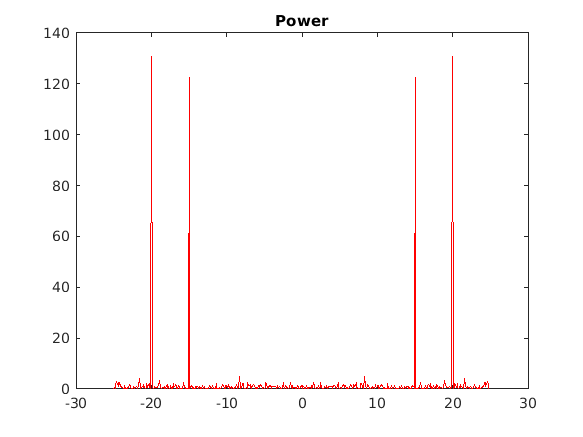

ynoise = fft(xnoise);
ynoiseshift = fftshift(ynoise);    
power = abs(ynoiseshift).^2/n; 
Color = "red";
plot(fshift,power,"Color",Color)
title('Power')